# Acrobot Simulations

Simulate a single acrobot, where the acrobot parameters are as close as possible to the ones of the experiment.

Take the parameters as follows:

- $m$ for the nominal energy is the average of $[ml, mt]$

- $l$ for the nominal energy is the average of $[lt,dt,ll,dl]$

- $\bar{q}_a = 1$ so that $q_a = \arctan(I p_u) \in [-\frac{\pi}{2},\frac{\pi}{2}]$

To choose our control parameter, notice that $E_\pi$ intersects the $p_u$-axis at $p_u = \sqrt{60m^2gl^3}$. Suppose we want to achieve a max actuator angle of $q_a^\text{rot}$ at this intersection point; then the associated control value becomes $I = \tan(q_a^\text{rot})/\sqrt{60m^2gl^3}$.

If we choose $q_a^\text{rot}$ to be $\frac{\pi}{3}$, we get $I = 9.28$. We round this up to $I = 10$ and use this as our control value.

% Setup the real acrobot's parameters
mt = 0.2112;  ml = 0.1979; % masses, kg
lt = 0.073;   ll = 0.083; % com, m
dt = 0.148;   dl = 0.145; % length of limbs, m
Jt = 0.00129; Jl = 0.00075; % moment of inertia
g = 9.81; % gravity, m/s^2

% Set up the symbolic variables for the real acrobot
qu = sym('qu','real'); % unactuated shoulder angle
qa = sym('qa','real'); % actuated leg angle
pu = sym('pu','real'); % unactuated momentum
pa = sym('pa','real'); % actuated momentum
assumeAlso(-pi < qu);
assumeAlso(qu <= pi);
assumeAlso(-pi < qa);
assumeAlso(qa <= pi);

% Set the control parameters
qb = 1; % qbar, in [0,1]
qarot = pi/3; % desired qa at E_pi
I = ceil(tan(qarot)/sqrt(60*m^2*g*l^3));
qaa = qb*atan(I*pu);

% Set up the dynamics
% Mass/Inertia matrix
M = [ml*dt^2+2*ml*cos(qa)*dt*ll+ml*ll^2+mt*lt^2 + Jl+Jt,...
                       ml*ll^2 + ml*dt*ll*cos(qa) + Jl; ...
        ml*ll^2 + ml*dt*ll*cos(qa) + Jl,   ml*ll^2 + Jl];

% Potential function
V = g*(ml*ll*(1 - cos(qu + qa)) + ...
    (ml*dt + mt*lt)*(1 - cos(qu)));
GquV = diff(V,qu);

% Energy
E = 1/2*[pu pa]*(M\[pu;pa]) + V;

% Define the VNHC and the actual pa
h = qa - qaa;
dhq = [diff(h,qu) diff(h,qa)];
dfp = diff(qaa,pu);
paa = -(dhq*(M\[0;1])) \ (dfp*GquV+dhq*(M\[1;0])*pu);
paa = subs(paa,qa,qaa);

% Dynamics
qud = subs(diff(E,pu),[qa pa],[qaa paa]);
pud = -subs(diff(E,qu),[qa pa],[qaa paa]);
qpd = [qud; pud];
qpdf = matlabFunction(qpd,'vars',[qu pu]);

% Convert it into a form that ode45 can use
fx = @(t,x)qpdf(wrapToPi(x(1)),x(2));

% Define the nominal VNHC at qa = 0
hnom = qa;
dhqnom = [diff(h2,qu) diff(h2,qa)];
dfpnom = 0;
paanom = (dhqnom*(M\[0;1])) \...
         (dfpnom*GquV+dhqnom*(M\[1;0])*pu);
paanom = subs(paanom,qa,0);

% Define the nominal energy function
Enom = subs(E,[qa pa],[0 paanom]);
Enomf = matlabFunction(Enom,'vars',[qu, pu]);

% Define the event for the ODE solver
E_event = @(t,qp) energyEvent(t,qp,Enomf,Enomf(pi,0));
baseOptions = odeset('RelTol',10e-14,...
                     'AbsTol',10e-14,...
                     'Events',E_event);
% Simulation time
T = 30;

## Part 1: Single Orbit Simulation

Initialize the acrobot at $q_u = \frac{\pi}{32}$ and show the orbit, tracking how long it takes the acrobot to remain outside of $E_\pi$. Also plot the nominal energy $E$.

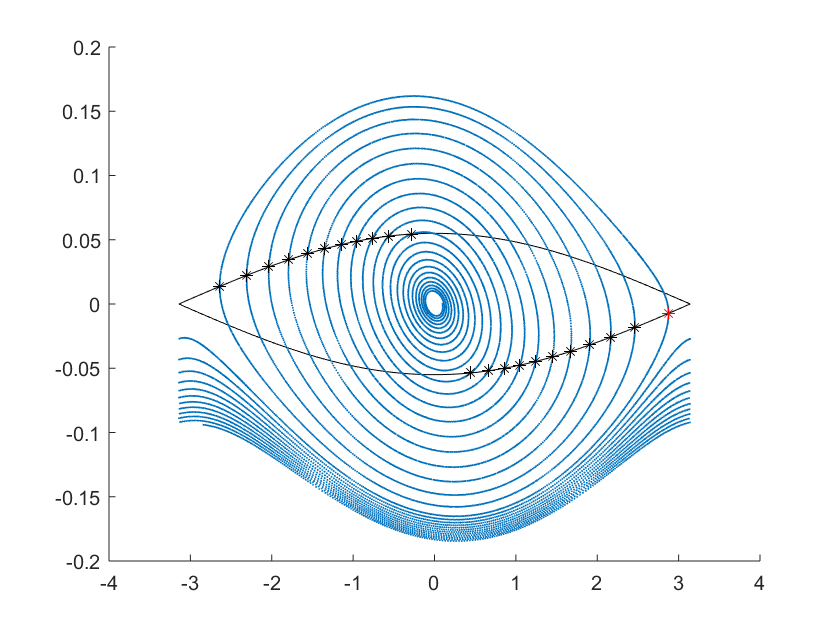

% Initial condition
qp0 = [pi/32;0];

% Simulate with an events trigger for when E = E_pi
sol = ode45(fx,[0,T],qp0,baseOptions);
% Wrap the qu values to the circle
sol.y(1,:) = wrapToPi(sol.y(1,:));
sol.ye(1,:) = wrapToPi(sol.ye(1,:));

% Plot the nominal E_pi
% First, we compute E_pi itself
Epi = Enomf(pi,0);
% Then we compute the value of E(0,1) to get the
% term in front of pu^2
E01 = Enomf(0,1);
% Finally, we know that E(pi,0)/2 gives us the term in
% front of (1-cos(qu)), so we can get that
% pu^2 = (E(pi,0) - E(pi,0)/2*(1-cos(qu))/E01
qs = linspace(-pi,pi,1000);
ps = sqrt(Epi/2*(2 - (1-cos(qs)))/E01);
orbitFig = figure;
hold on;
plot(qs,ps,'k',qs,-ps,'k');
% Now plot the orbit, with scatter point size 0.5 so
% it looks nice
scatter(sol.y(1,:),sol.y(2,:),0.5);
% Show the last time it exits the orbit in red, and every
% other time in black
scatter(sol.ye(1,:),sol.ye(2,:),'k*');
scatter(sol.ye(1,end),sol.ye(2,end),'r*');
hold off;
saveas(orbitFig,'images/acrobot_orbit','png');
saveas(orbitFig,'images/acrobot_orbit','fig');

## Part 2: Monte-Carlo Simulation

Take as a metric the energy of the nominal pendulum. Randomly initialize the acrobot inside $E(\delta,0)$ for some $\delta > 0$, and measure how long it takes for the acrobot to begin rotating.

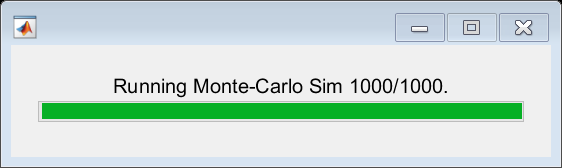

% Initialize the random number generator
rng('shuffle');

% Change the events function to measure how long it
% takes the acrobot to reach a rotation at qu = pi.
mcOptions = odeset(baseOptions,'Events',@rotationEvent);

% Set the number of trials for the monte carlo method
N = 1000;

% Set the sublevel set as the energy level delta,
% where it is of the form E(delta,0)
delta = pi/32;

% Now initialize N points inside that energy sublevel set
% by taking a random value qu \in [-q0max,q0max] ...
q0s = -delta + 2*delta*rand(1,N);
% ... and find the value p(q0) which satisfies
% E(delta,0) = E(q0,p(q0)), which is the same as
% p(q0)^2 = E(pi,0)/(2*E(0,1)) * (cos(q0) - cos(delta))
pq = sqrt(Epi/2*(cos(q0s) - cos(delta))/E01);
% To set our initial conditions, choose a random pu value
% in [-p(q0), p(q0)].
p0s = -pq + 2*pq.*rand(1,N);
x0s = [q0s;p0s];

% Vector to store how long it takes to rotate
tRot = zeros(1,N);

% Set a progress bar for our simulation
bar = waitbar(0,'Please Wait...');
% Now simulate with the monte carlo method
for i = 1:N
    % Update the waitbar
    waitbar(i/N,bar,...
        sprintf('Running Monte-Carlo Sim %d/%d.',i,N));
    % Get the initial condition
    x0 = x0s(:,i);
    % Simulate using ode45
    soli = ode45(fx,[0,T],x0,baseOptions);

    % If the hitting time is empty, repeat this 
    % simulation with a longer time
    % First, set a variable to store the additional time
    Tadd = 0;
    while isempty(soli.xe)
        % Add 5 seconds to the "time to add" variable
        Tadd = Tadd + 5;
        % Update the progress bar to inform the user
        % that we are in this while-loop
        waitbar(i/N,bar,...
          sprintf('Repeating MC %d, adding %d seconds.',...
                  i, Tadd));
        % Repeat the simulation
        soli = ode45(fx,[0,T+Tadd],x0,baseOptions);
    end
    %
     % Extract how long it took to rotate
    tRot(i) = soli.xe(1);
end

close(bar);

% Save all our data for the monte-carlo sims
mcData.delta = delta;
mcData.x0s = x0s;
mcData.tRot = tRot;

today = datetime;
fname = sprintf('data/acrobot_mc_%d_%d_%d',...
    day(today),...
    month(today),...
    year(today));
save(fname,'mcData');

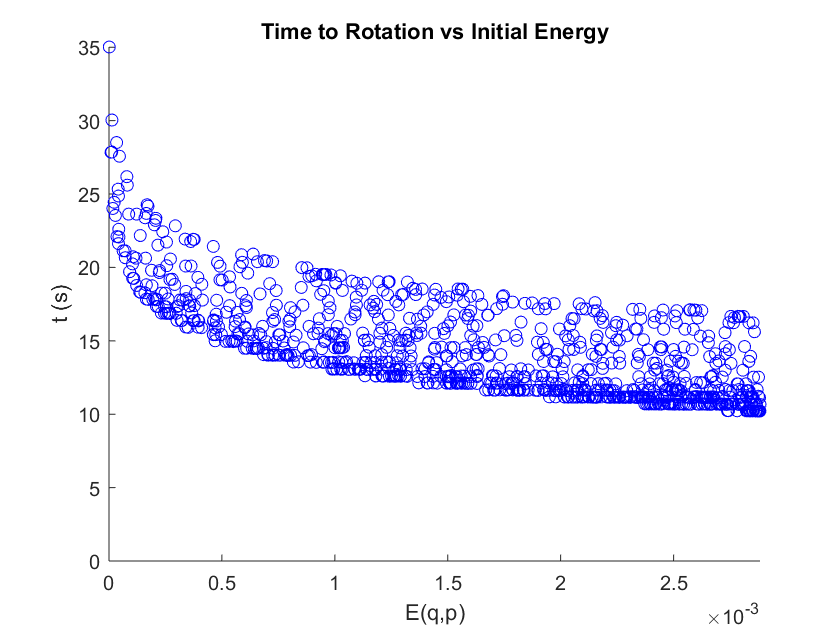

% Get the average of the first and last hitting times
%tRotAvg = mean(mcData.tRot);

% Plot first/last hitting time as a function of energy
% E(q0,p0)
mcFig = figure;
hold on;
scatter(Enomf(q0s,p0s),tRot,'b');
% Show the average times
axis([0 max(Enomf(q0s,p0s)) 0 max(tRot)])
ax = axis;
%plot(ax(1:2),[tRotAvg,tRotAvg],'k--');
hold off;
title('Time to Rotation vs Initial Energy');
xlabel('E(q,p)');
ylabel('t (s)');

saveas(mcFig,'images/acrobot_mc','png');
saveas(mcFig,'images/acrobot_mc','fig');